% Leman FENG, sub-pixel Exo 1
D = 1;
f = 1;
lambda = 1;
c = pi*pi*D^4/32/f/f;

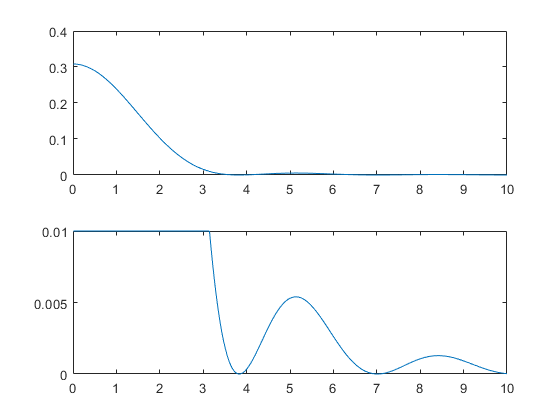

% Question 1
r = 0.01:0.01:10;
K = c * (2*besselj(1,r)./r).^2;
figure;
subplot(2,1,1)
plot(r,K);
subplot(2,1,2);
plot(r,min(K,0.01));

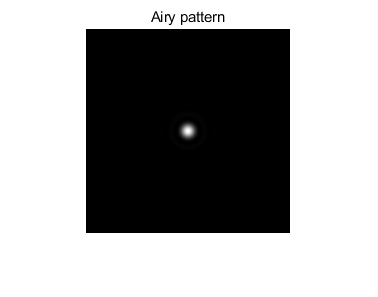

% Question 2
a = 10;
N = 204;
T = 2*a/N; % sampling distance
[X1,X2] = meshgrid(linspace(-a,a,N),linspace(-a,a,N));
absX = sqrt(X1.^2+X2.^2);
r = absX*D*pi/lambda/f;
Airy = c*(2*besselj(1,r)./r).^2;
figure;
imshow(Airy,[]);
title('Airy pattern');

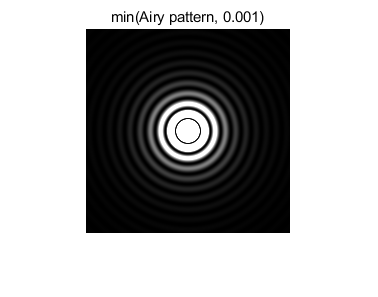

figure;
imshow(Airy,[0,0.001]);
title('min(Airy pattern, 0.001)');

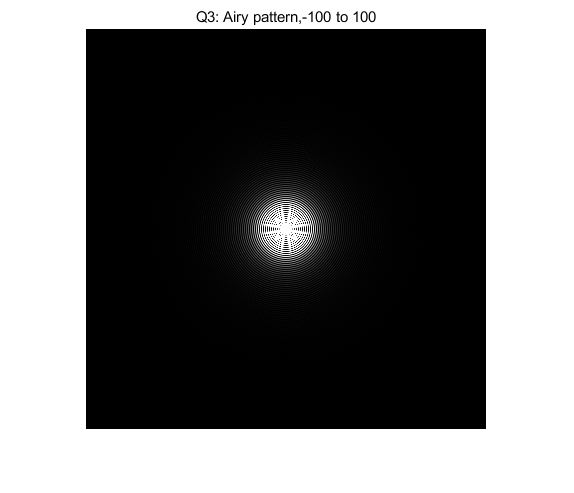

% Question 3
a = 100;
N = 400;
T = 2*a/N; % sampling distance
[X1,X2] = meshgrid(linspace(-a,a,N),linspace(-a,a,N));
absX = sqrt(X1.^2+X2.^2);
r = absX*D*pi/lambda/f;
Airy = c*(2*besselj(1,r)./r).^2;
figure;
imshow(Airy,[0,0.00001]);
title('Q3: Airy pattern,-100 to 100');

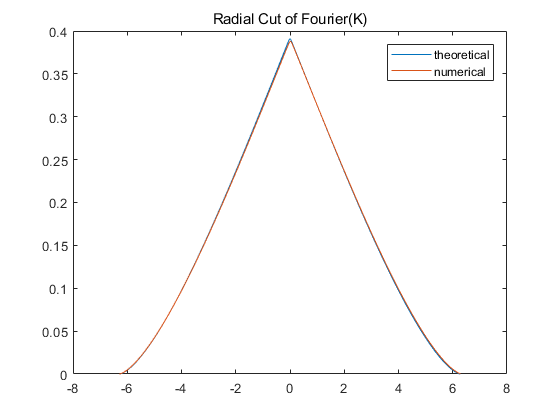


b=1/T/2;
[nu1,nu2] = meshgrid(linspace(-b,b,N),linspace(-b,b,N));
% nu is the frequency
ksi1 = nu1*2*pi;
ksi2 = nu2*2*pi;
% ksi is the angular frequency
rho = sqrt(ksi1.^2+ksi2.^2) * lambda * f /2/pi/D;
F_K = lambda^2*D^2/4 * (acos(rho) - rho.*sqrt(1-rho.*rho)).*(rho<1);

% multiple T/2 to transform FFT to a CFT estimate
F_K_num = T/2*abs(fftshift(fft2(Airy)));

figure;
plot(ksi1(200,:), F_K(200,:));
hold on;
plot(ksi1(200,:), F_K_num(200,:));
title('Radial Cut of Fourier(K)');
legend('theoretical','numerical');

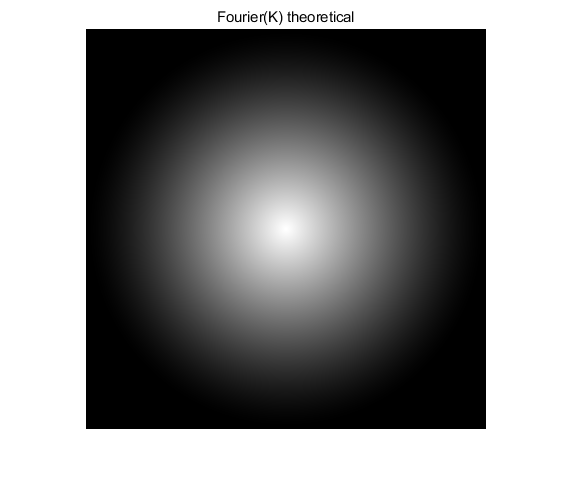


figure;
imshow(abs(F_K),[]);
title('Fourier(K) theoretical');

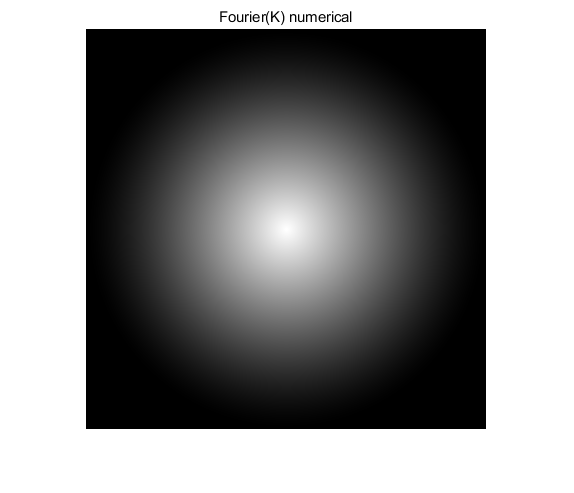



figure;
imshow(F_K_num,[]);
title('Fourier(K) numerical');

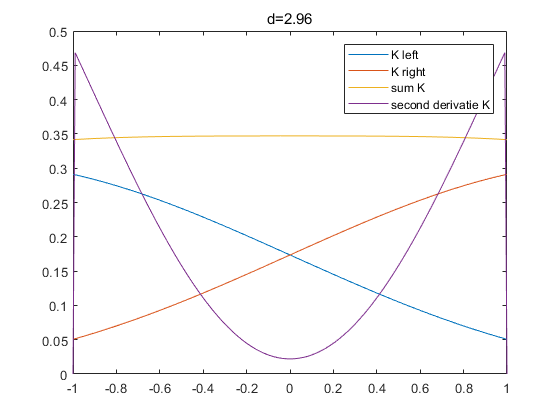

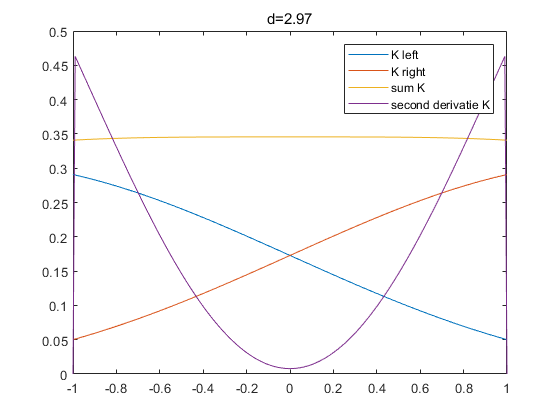

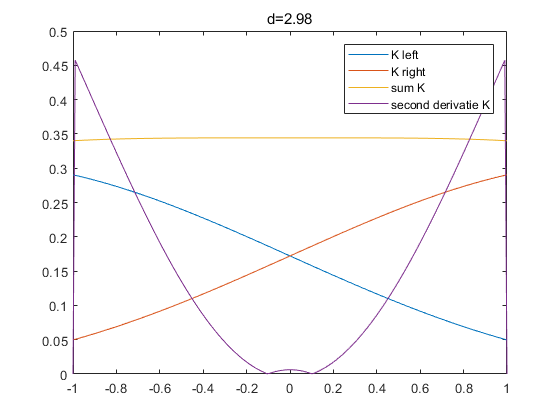

% Question 4
r = linspace(-1,1,200);
for d = 2.96:0.01:2.98
    K_left = c * (2*besselj(1,r+d/2)./(r+d/2)).^2;
    K_right = c * (2*besselj(1,r-d/2)./(r-d/2)).^2;
    figure;
    plot(r,K_left);
    hold on;
    plot(r,K_right);
    Ksum = K_right+K_left;
    plot(r,Ksum);
    ddKsum = conv(Ksum,[-1,2,-1]);
    ddKsum = [0,ddKsum(3:end-2),0];
    plot(r,abs(ddKsum)*100000);
    title(['d=',num2str(d)])
    legend('K left','K right','sum K', 'second derivatie K')
end


% so we take d = 2.98
% Rayleigh's criterion is d = 3.83
% 2.97/3.83 = 0.78

Question 5

As seen in course, we can set $R\mathbf{x}=[0,|\mathbf{x}|]$

Then

 
$$K_{diff}(\mathbf{x})=K_{diff}(R\mathbf{x})=\frac{1}{2f^2}|\int_{\epsilon D/2}^{D/2}\int_{-\pi}^\pi \exp{(\frac{2i\pi}{\lambda f}|\mathbf{x}|r\sin{\theta})} d\theta udu|^2$$


The imaginary part is canceled out, we have:


$$K_{diff}(\mathbf{x})=\frac{1}{2 f^2}| \int_{\epsilon D/2}^{D/2} \int_{0}^\pi \cos{(\frac{2\pi}{\lambda f}|\mathbf{x}|r\sin{\theta})} d\theta udu|^2$$


Set $t = \frac{2\pi}{\lambda f}|\mathbf{x}| u$, $r = \frac{\pi D |\mathbf{x}|}{\lambda f}$


$$K_{diff}(\mathbf{x})=\frac{2}{f^2}|\int_{\epsilon \rho}^{\rho}\int_{0}^\pi \cos{(t\sin{\theta})} d\theta  \frac{D^2}{4r^2} tdt|^2$$



$$K_{diff}(\mathbf{x})=\frac{\pi^2 D^4}{8 f^2 r^4}|\int_{\epsilon r}^{r}   t J_0(t)  dt|^2$$



$$K_{diff}(\mathbf{x})=\frac{\pi^2 D^4}{8 f^2 r^4} | r (1-\epsilon)(J_1(r)-J_1(\epsilon r)) |^2$$



$$K_{diff}(\mathbf{x})=(1-\epsilon)^2 \frac{\pi^2 D^4}{32 f^2 } |\frac{2(J_1(r)-J_1(\epsilon r))}{r} |^2$$



$$K_{diff}(\mathbf{x})=(1-\epsilon)^2 C |\frac{2(J_1(r)-J_1(\epsilon r))}{r} |^2$$


where $r = \frac{\pi D |\mathbf{x}|}{\lambda f},  \ C =  \frac{\pi^2 D^4}{32 f^2 }$

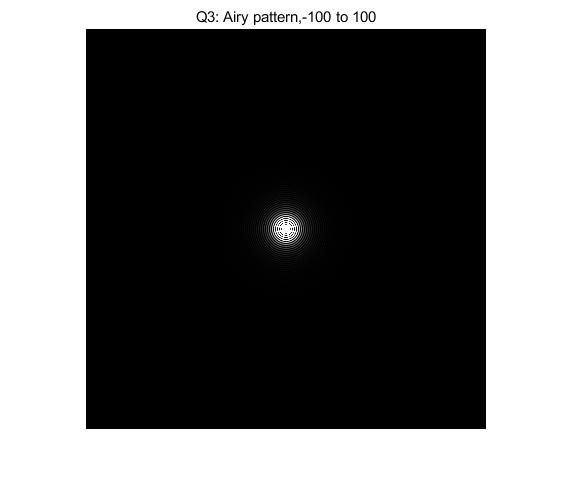

% Question 6
a = 100;
N = 400;
T = 2*a/N; % sampling distance
epsilon = 0.25;
[X1,X2] = meshgrid(linspace(-a,a,N),linspace(-a,a,N));
absX = sqrt(X1.^2+X2.^2);
r = absX*D*pi/lambda/f;
Airy = c*(2*besselj(1,r)./r).^2;
Airy_epsilon =(1-epsilon)^2 * c*(2*(besselj(1,r)-besselj(1,epsilon*r))./r).^2;
figure;
imshow(Airy,[0,0.0001]);
title('Q3: Airy pattern,-100 to 100');

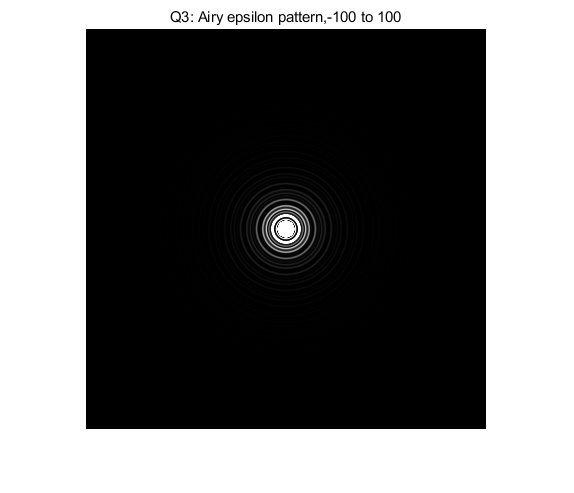

imshow(Airy_epsilon,[0,0.0001]);
title('Q3: Airy epsilon pattern,-100 to 100');

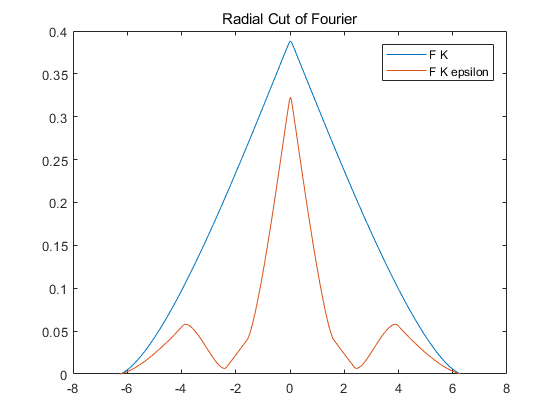


b=1/T/2;
[nu1,nu2] = meshgrid(linspace(-b,b,N),linspace(-b,b,N));
% nu is the frequency
ksi1 = nu1*2*pi;
ksi2 = nu2*2*pi;
% ksi is the angular frequency
rho = sqrt(ksi1.^2+ksi2.^2) * lambda * f /2/pi/D;


% multiple T/2 to transform FFT to a CFT estimate
F_K_num = T/2*abs(fftshift(fft2(Airy)));
F_K_epsilon_num = T/2*abs(fftshift(fft2(Airy_epsilon)));

figure;
plot(ksi1(200,:), F_K_num(200,:));
hold on;
plot(ksi1(200,:), F_K_epsilon_num(200,:));
title('Radial Cut of Fourier');
legend('F K','F K epsilon');

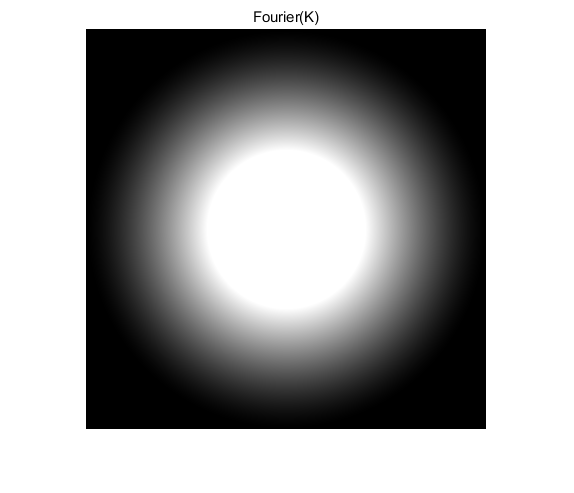


figure;
imshow(F_K_num,[0,0.2]);
title('Fourier(K)');

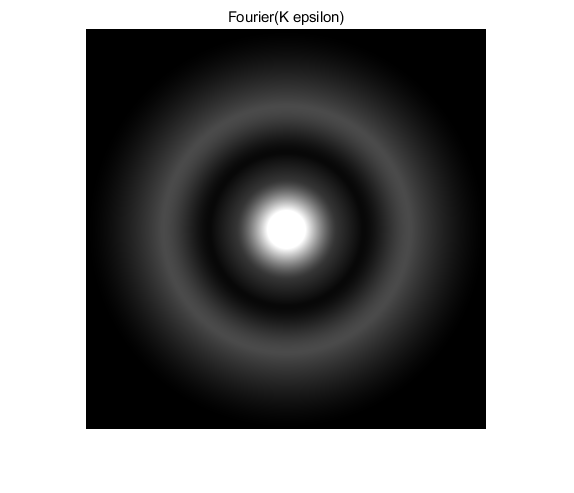



figure;
imshow(F_K_epsilon_num,[0,0.2]);
title('Fourier(K epsilon)');

The occlusion in center doesn't change the resolution of optical system.